# Mehr Diagramme

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 8);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["year", "month", "tmax", "tmin", "af", "rain", "sun", "station"];
opts.VariableTypes = ["int16", "int8", "double", "double", "categorical", "double", "double", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["af", "station"], "EmptyFieldRule", "auto");

% Import the data
weatherD = readtable("C:\Users\Ioannis\Downloads\MET_Office_Weather_Data.csv", opts);

% Clear temporary variables
clear opts

% Remove missing entries
wDfixed = rmmissing(weatherD);

## Aufgabe 1: Bereitstellen von Datensets

Ausgangslage für die Graphen sind immer Daten.  Wir brauchen also geeignete Datensets, um sie entsprechend darzustellen.

Wir verwenden wieder unseren Datensatz `MET Office Weather Data.csv``.`

Erstellen Sie ein Datenset 

- `yearlyMeanPerStation``: `Gruppierung nach station, jahr, mit den Aggregatsfunktionen median und mean und den Messwerten tmin, tmax, sun, rain

- `monthlyMeanPerStation``: `Gruppierung nach station, jahr, monat mit den Aggregatsfunktionen median und mean und den Messwerten tmin, tmax, sun, rain

- `monthlyMean``: `Gruppierung nach monat mit den Aggregatsfunktionen median und mean und den Messwerten tmin, tmax, sun, rain

yearlyMeanPerStation = groupsummary(wDfixed,{'station','year'},{'median','mean'},{'tmin','tmax','sun','rain'});
monthlyMeanPerStation = groupsummary(wDfixed,{'station','year','month'},{'median','mean'},{'tmin','tmax','sun','rain'});
monthlyMean = groupsummary(wDfixed,'month',{'median','mean'},{'tmin','tmax','sun','rain'});

## Aufgabe 2: 

Zeichnen Sie einen Boxplot, welcher die `monthlyMeanPerStation.median_tmin` Werte für alle Monate anzeigt. Funktion ***boxplot(..)***. Wenn Sie nicht sicher sind, schauen Sie in der Matlab Dokumentation nach

- Fügen Sie einen passenden Titel in das Diagramm ein (title())

-  Fügen Sie ein passendes Label für die X und Y-Achse ein (xlabel(), ylabel())

- Überlegen Sie sich, was aus dieser Graphik gut sichtbar wird.

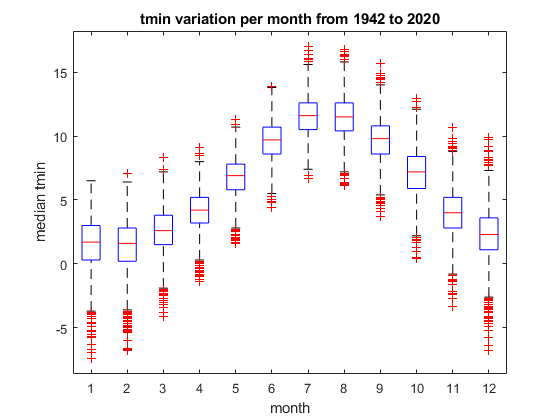

boxplot(monthlyMeanPerStation.median_tmin, monthlyMeanPerStation.month);
xlabel("month");
ylabel("median tmin");
title("tmin variation per month from 1942 to 2020")

## Aufgabe 3: 

Zeichnen Sie ein Balkendiagramm des Wertes `monthlyMean`***.***`median_rain``. `Matlab Funktion ***bar(..)***.

- Fügen Sie einen Titel und eine passende Beschreibung der Achsen hinzu.

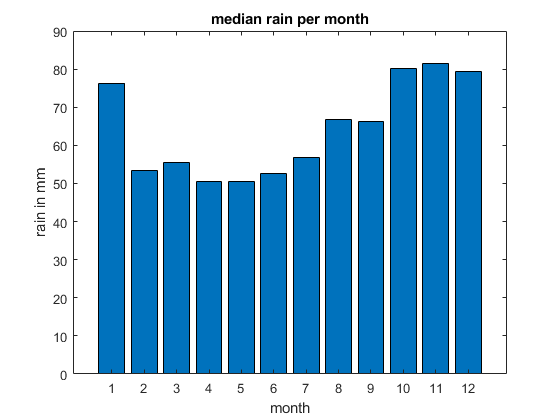

bar(monthlyMean.median_rain);
xlabel("month")
ylabel("rain in mm")
title("median rain per month")

## Aufgabe 4: 

Zeichnen Sie dasselbe Diagramm wie in 2 aber mit einer y Achsenbeschränkung von [50 90]. (Matlab Funktion [ylim(..)](https://www.mathworks.com/help/matlab/ref/xlim.html)) Vergleichen Sie das Resultat mit 2. Was sagen Sie dazu?

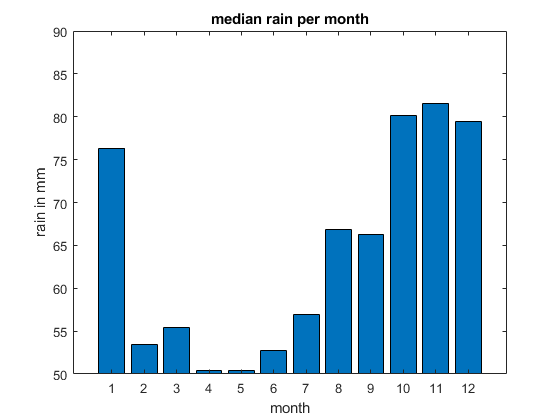

ylim([50 90]);

%with these limits, the diagram suggests that there is a huge difference in
%rain fall between Nov and May which is not really true
%hence the selection of limits influences the intepretation of the diagram!

## Aufgabe 5: 

Zeichen Sie ein Balkendiagramm der Werte `monthlyMean`***.***`median_tmin`` und ``monthlyMean`***.***`median_tmax``.` Es soll einen Balken für tmin und tmax für jeden Monat dargestellt werden (Sie müssen die zwei Messreihen in einer Matrix kombinieren).

- Fügen Sie eine Legende ein, welche die Datenreihen tmin und tmax aufführt. 

- Vergleichen Sie dieses Diagramm mit einem Linien-Diagramm, welches dieselben zwei Werte darstellt. 

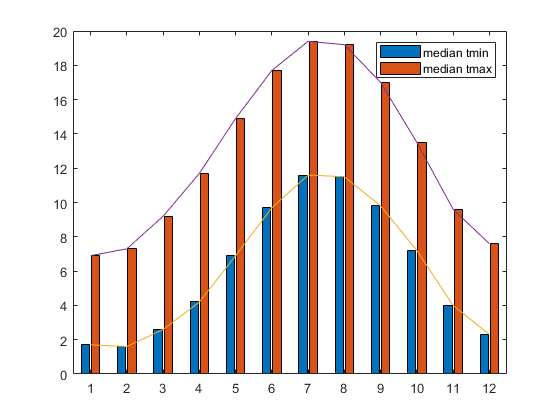

data = [monthlyMean.median_tmin monthlyMean.median_tmax];
bar( data );
hold on
plot( data );
legend("median tmin", "median tmax");
hold off

## Aufgabe 6:

Zeichnen Sie ein Linien-Diagramm, welches sowohl die Werte `monthlyMean`***.***`median_rain`  als auch `monthlyMean`***.***`median_sun`  darstellt. Hier haben wir offensichtlich das Problem, dass wir nicht beide Datenelemente mit derselben Ordinate darstellen können. Wir müssen also den einen Wert auf der linken Y-Achse beschreiben und den anderen auf der rechten Y- Achse. Wie Sie das tun können ist [hier](https://www.mathworks.com/help/matlab/creating_plots/plotting-with-two-y-axes.html) beschrieben.

- Wählen Sie die Linienfarbe für den «regen» = blau und für die «sonne» = rot

- Wählen Sie für beide Linien einen unterschiedlichen «linestyle»

- Fügen Sie eine passende Legende zum Diagramm hinzu.

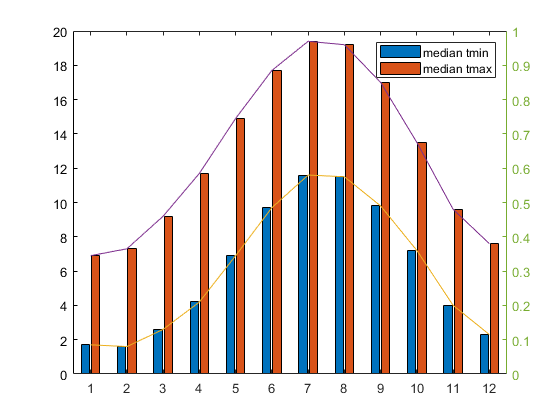

hold off
yyaxis left
plot( monthlyMean.median_rain, "color", "b", "linestyle","-." );

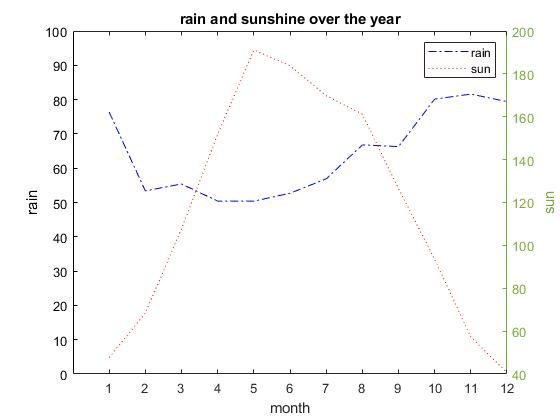

ylim([0 100])
ylabel("rain");
hold on
yyaxis right
plot( monthlyMean.median_sun, "color", "r", "linestyle",":" );
ylabel("sun");
hold off
xlabel("month")
title("rain and sunshine over the year")
legend("rain", "sun")

## Aufgabe 7:

Kombinieren Sie Diagramm 1, 2 und 5 in einem Chart. Alle drei Diagramme sollen untereinanderstehen. Verwenden Sie die Matlab Funktionen tiledlayout(..) und nexttile. Eine Beschreibung für das Anordnen mehrerer Diagramm in einem Chart finden Sie [hier](https://www.mathworks.com/help/matlab/ref/tiledlayout.html). Sie brauchen nur den Abschnitt «Create 2-by 2 Layout» anzuschauen. Von Bedeutung sind nur die Funktionen `tiledlayout(rows, cols)` sowie `nexttile()`. Beachten Sie, dass nexttile einen Rückgabewert hat. Diesen können Sie verwenden, um nachträglich einen bestimmten *«tile»* mit legenden usw. zu versehen (vergl. [https://www.mathworks.com/help/matlab/ref/nexttile.html#mw_7d4bb569-8c5a-470d-ade6-cc2a214a3e38).](https://www.mathworks.com/help/matlab/ref/nexttile.html#mw_7d4bb569-8c5a-470d-ade6-cc2a214a3e38).)

hold off
tiledlayout(3,1);

l1 = nexttile;

%aus Aufgabe 1
boxplot(l1, monthlyMeanPerStation.median_tmin, monthlyMeanPerStation.month);

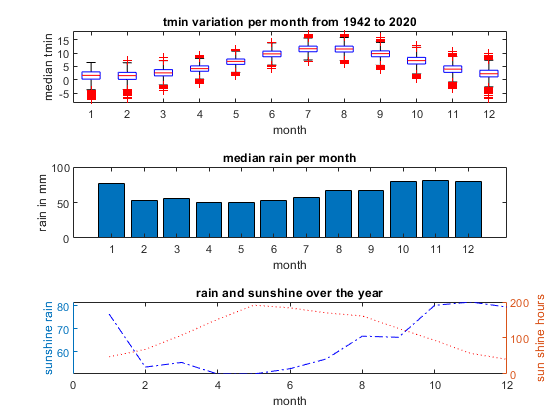

xlabel(l1, "month");
ylabel(l1, "median tmin");
title(l1, "tmin variation per month from 1942 to 2020")

%aus Aufgabe 2
l2 = nexttile;
bar(l2, monthlyMean.median_rain);
xlabel(l2, "month");
ylabel(l2, "rain in mm");
title(l2, "median rain per month");

%aus Aufgabe 5
l3 = nexttile;
yyaxis left

plot(l3, monthlyMean.median_rain, "color", "b", "linestyle","-." );
ylabel(l3,"sunshine rain");
hold on
yyaxis right
plot( l3, monthlyMean.median_sun, "color", "r", "linestyle",":" );
ylabel(l3,"sun shine hours");
hold off;
xlabel(l3,"month")
title(l3,"rain and sunshine over the year")
tiledlayout(1,1)

## Aufgabe 8:

Erstellen Sie ein Histogramm der Daten `yearlyMeanPerStation.median_tmin``.` Verwenden Sie dazu die Funktion ***histogram(..)***. Speichern Sie den Rückgabewert der Funktion histogram() in einer Variablen h.

- fügen Sie ein passendes Label für die X und Y-Achsen hinzu.

- setzen Sie das Property h.Normalisation:`h.Normalization = "probability";`  Was passiert? Wie Interpretieren Sie das Diagramm jetzt?

- schauen Sie sich die Variable ***h*** an. Was stellen Sie fest?

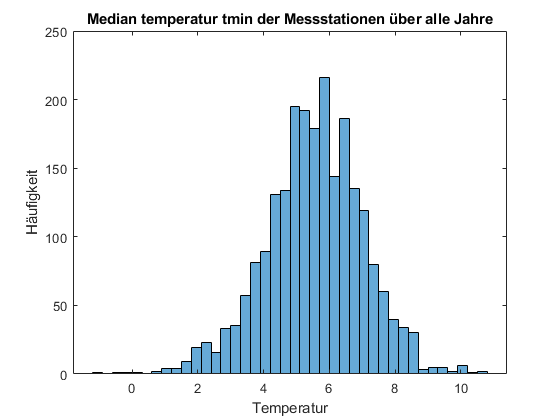

h = histogram( yearlyMeanPerStation.median_tmin );
title( "Median temperatur tmin der Messstationen über alle Jahre" );
xlabel("Temperatur");
ylabel("Häufigkeit");